## **Dimensionnement d'un convertisseur LLC**

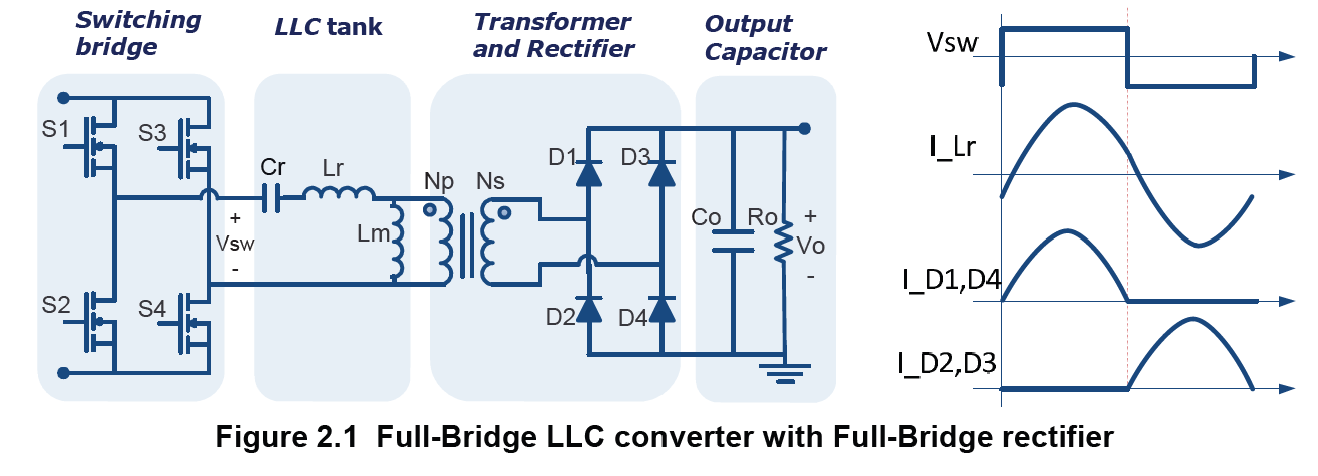

**Cahier des charges : **

Tension d'entrée : 

Ve=48; % V

Tension de sortie min : 

Vsmin=15000; % V

Tension de sortie max : 

Vsmax=25000; % V

Tension de sortie nominale : 

Vs=20000; % V

Puissance en sortie : 

Ps=50; % W

Fréquence de découpage approximative : 

Fs=200000; % Hz

Calcul de la charge (résistive) équivalente en sortie : 

Rs=Vs^2/Ps % Ohm

Rs = 8000000

Facteur de multiplication de l'étage multiplicateur : 

Mult=10;

Tension de sortie du convertisseur LLC : 

Vo=Vs/Mult % V

Vo = 2000

Résistance équivalente ramenée en sortie de LLC : 

Ro=Vo^2/Ps % Ohm

Ro = 80000

Rapport tension sortie LLC/entrée : 

n=Vo/Ve

n = 41.6667

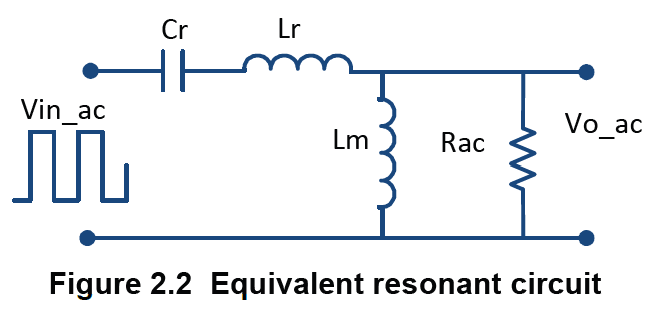

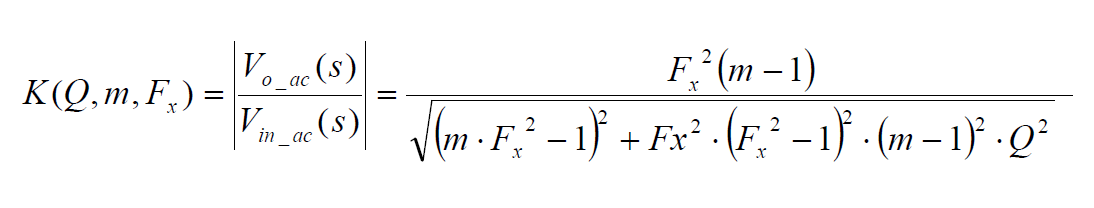

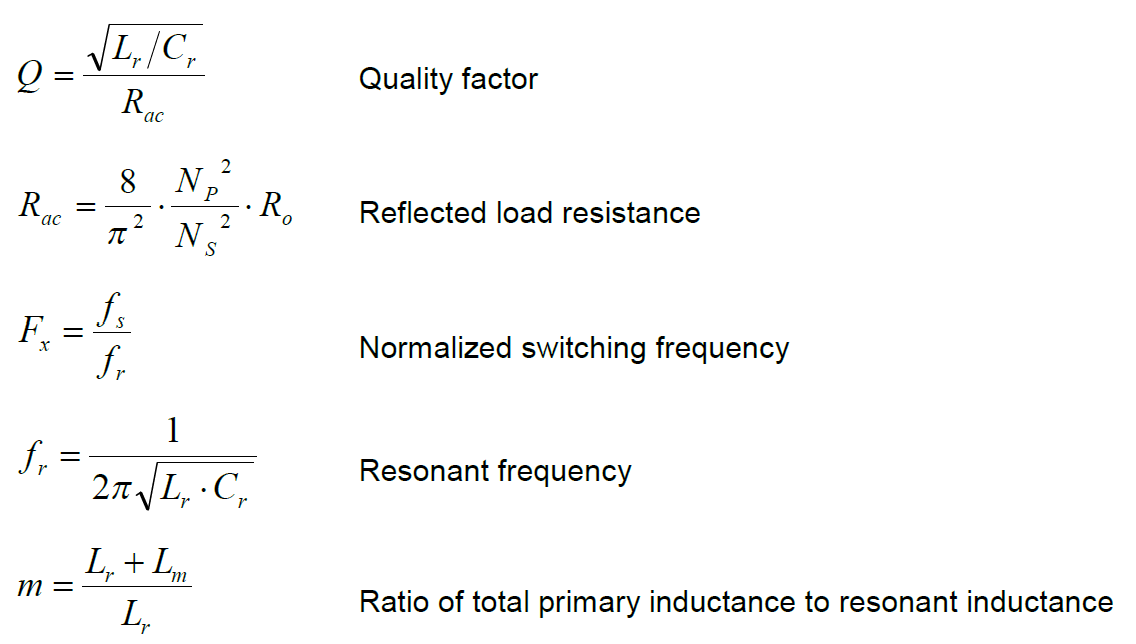

Gain de la cellule résonnante :

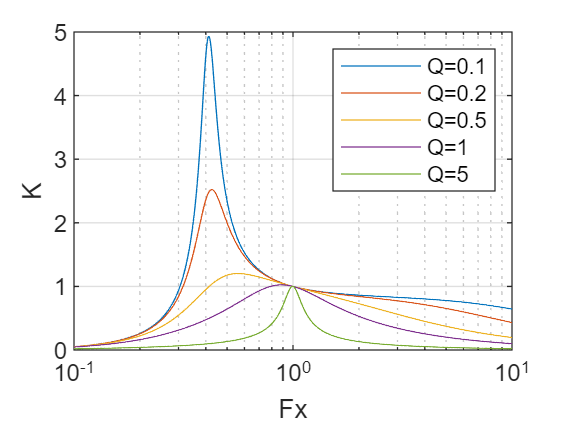

Fx=logspace(-1,1,1000); % Fréquence normalisée
m=6;
Q=[0.1,0.2,0.5,1,5];
for i=1:1:length(Q)
    K=Fx.^2*(m-1)./sqrt((m*Fx.^2-1).^2+Fx.^2.*(Fx.^2-1).^2*(m-1)^2*Q(1,i).^2);
    semilogx(Fx,K,'DisplayName',strcat('Q=',num2str(Q(1,i))))
    hold on
end
grid on
legend();
xlabel('Fx')
ylabel('K')


disp('On table sur un gain de la cellule de')

On table sur un gain de la cellule de


Kcel=4

Kcel = 4

Q=0.1

Q = 0.1000

disp('On lit alors une fréquence normalisée : ')

On lit alors une fréquence normalisée : 


Fxn=0.44

Fxn = 0.4400

disp('Et une fréquence normalisée minimale : ')

Et une fréquence normalisée minimale : 


Fxmin=0.415

Fxmin = 0.4150

Calcul du rapport de transformation Ns/Np du transformateur pour le gain Kcel considéré : 

Ntransfo=Vo/(Ve*Kcel)

Ntransfo = 10.4167


Rac=(8/pi^2)*(1/Ntransfo^2)*Vo^2/Ps

Rac = 597.6167


Fr=Fs/Fxn

Fr = 4.5455e+05


Lr=Rac*Q/(2*pi*Fr)

Lr = 2.0925e-05


Cr=1/(4*pi^2*Fr^2*Lr)

Cr = 5.8590e-09


Lm=Lr*(m-1)

Lm = 1.0463e-04